function [a, b] = base(P1, P2, P3)
    % Construction de la matrice des coordonnées des sommets
    M = [P1(1), P1(2), 1;
         P2(1), P2(2), 1;
         P3(1), P3(2), 1];
    
    % Matrice identité pour résoudre le système
    identity = eye(3);
    
    % Résolution du système linéaire M * coeffs = identity
    coeffs = M \ identity;
    
    a = coeffs(1:2, :); % Les deux premières lignes pour les coefficients linéaires
    b = coeffs(3, :);   % La dernière ligne pour les termes constants
end

function [S, G] = geo(P1, P2, P3)
    % Surface du triangle (formule utilisant le déterminant)
    S = abs(det([P1(1), P1(2), 1;
                 P2(1), P2(2), 1;
                 P3(1), P3(2), 1])) / 2;
             
    % Barycentre
    G = (P1 + P2 + P3) / 3;
end

% Construction et maillage de omega1 : Square [-1;1]^2
nodes = [-1 -1; -1 1; 1 1;1 -1];
omega1 = Domain(nodes);
mesh1 = Mesh(omega1,0.1);

buiding mesh v2.4_beta
mesh done



% Récupération du couple (P,T) correspondant et des points du bord
P_omega1 = mesh1.nodes ;
T_omega1 = mesh1.triangles;
bord_omega1 = mesh1.boundary;

% Construction et maillage de omega2 : Disc(0,1) 
nodes = [1 0];
edges = {{1,1,'cos(t)','sin(t)',[0,2*pi]}};
omega2 = Domain(nodes,edges);
mesh2 = Mesh(omega2,0.1);

buiding mesh v2.4_beta
mesh done



% Récupération du couple (P,T) correspondant et des points du bord
P_omega2 = mesh2.nodes;
T_omega2 = mesh2.triangles;
bord_omega2 = mesh2.boundary;


% Construction et maillage de omega3 : Square with a hole
nodes = [-1 -1; -1 1; 1 1;1 -1;0.5 0];
edges = {{1,2},{2,3},{3,4},{4,1},{5,5,'0.5*cos(t)','0.5*sin(t)',[0,2*pi],'r'}};
omega3 = Domain(nodes,edges);
mesh3 = Mesh(omega3,0.1);

buiding mesh v2.4_beta
mesh done


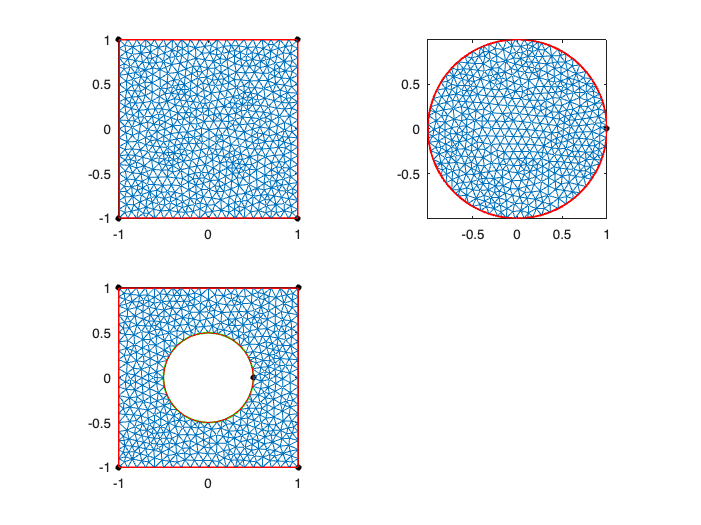


% Récupération du couple (P,T) correspondant et des points du bord
P_omega3 = mesh3.nodes;
T_omega3 = mesh3.triangles;
bord_omega3 = mesh3.boundary;
% Visualisation des domaines et de leurs maillages 
subplot (2,2,1); omega1.plot; hold on; mesh1.plot; axis equal
subplot (2,2,2); omega2.plot; hold on; mesh2.plot; axis equal
subplot (2,2,3); omega3.plot; hold on; mesh3.plot; axis equal

clear all 


# Exercice 2

Q16

nodes1 = [0 0; 6 0; 6 4; 0 4; 1.6 1; 3.6 1; 5.6 1];

edges1 = {
    {1, 2},                 
    {2, 3},                  
    {3, 4},                  
    {4, 1},                  
    {5, 5, '0.6*cos(t)+1', '0.6*sin(t)+1', [0, 2*pi], 'r'}, 
    {6, 6, '0.6*cos(t)+3', '0.6*sin(t)+1', [0, 2*pi], 'r'}, 
    {7, 7, '0.6*cos(t)+5', '0.6*sin(t)+1', [0, 2*pi], 'r'}  
};

% Création du domaine
omega4 = Domain(nodes1, edges1);

mesh4 = Mesh(omega4, 0.1);

buiding mesh v2.4_beta
mesh done




P_omega4 = mesh4.nodes;       
T_omega4 = mesh4.triangles;   
bord_omega4 = mesh4.boundary; 

% Affichage du domaine et du maillage
figure;
omega4.plot(); 
hold on;
mesh4.plot();

Q17

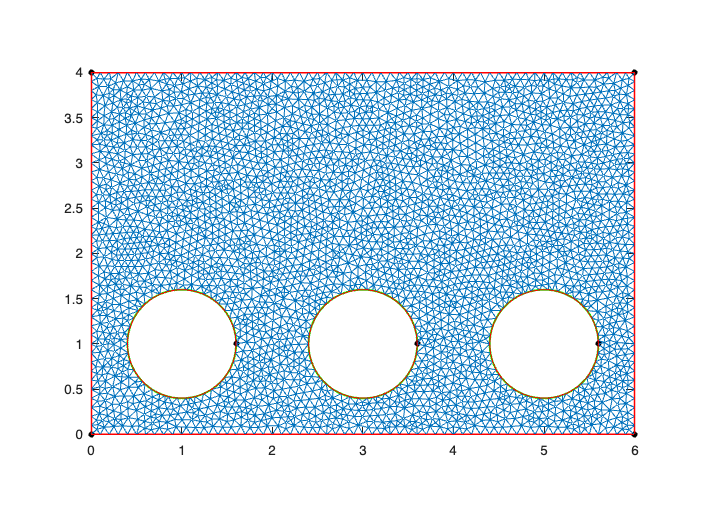

% Les conditions de Neuman sont implicite, on a pas besoin de faire de
% modification sur les bords
% Bords du domaine
gamma_iso = unique([mesh4.boundary(1); mesh4.boundary(2); mesh4.boundary(4)]); % Bords isolants
gamma_ext = mesh4.boundary(3);  % Bord externe
gamma_tube = unique([mesh4.boundary(5); mesh4.boundary(6); mesh4.boundary(7)]); % Bords des tubes

% Fonction source et conditions aux limites
f = @(x, y) 0;  % Fonction source (néant dans ce cas)
% Conditions au bords
g_ext = @(x, y) 0;  % Condition Dirichlet sur gamma_ext
g_tube = @(x, y) 1;  % Condition Dirichlet sur gamma_tube

% Initialisation des données
N = size(P_omega4, 1);
A = sparse(N, N);    
b = zeros(N, 1);     

for k = 1:size(T_omega4, 1)
    nodes = T_omega4(k, :);    
    coords = P_omega4(nodes, :);
   
    [a, b_local] = base(coords(1, :), coords(2, :), coords(3, :));
    
    % Calcul de l'aire du triangle
    Area = 0.5 * abs(det([[1 1 1]', coords]));
    
    % Construction de la matrice locale Ak
    Ak = Area * (a' * a);  
    centroid = mean(coords);  
    bk = Area * f(centroid(1), centroid(2)) * [1; 1; 1] / 3; 
    
    % Assemblage global
    A(nodes, nodes) = A(nodes, nodes) + Ak; 
    b(nodes) = b(nodes) + bk;              
end

% Conditions de Dirichlet sur gamma_ext
for n = gamma_ext'
    A(n, :) = 0; A(n, n) = 1;  % Modification de la matrice pour Dirichlet
    b(n) = g_ext(P_omega4(n, 1), P_omega4(n, 2)); % Valeur imposée
end

% Conditions de Dirichlet sur gamma_tube
for n = gamma_tube'
    A(n, :) = 0; A(n, n) = 1;  % Modification de la matrice pour Dirichlet
    b(n) = g_tube(P_omega4(n, 1), P_omega4(n, 2)); % Valeur imposée
end

% Résolution du système linéaire
u = A \ b;

% Visualisation de la solution
figure;
trisurf(T_omega4, P_omega4(:, 1), P_omega4(:, 2), u, 'EdgeColor', 'none');
xlabel('x'); ylabel('y'); zlabel('u(x,y)');
title('Solution du problème thermique');
colorbar;

Q 18

% Calcul du flux thermique sortant
% Fonction test w : définie pour le bord gamma_ext
w = zeros(N, 1);
w(gamma_ext) = 1; % w = 1 sur gamma_ext, 0 ailleurs

% Calcul de l'intégrale pour le flux
flux = 0;
for k = 1:size(T_omega4, 1)
    nodes = T_omega4(k, :);      
    coords = P_omega4(nodes, :); % Coordonnées des nœuds du triangle
    [a, b_local] = base(coords(1, :), coords(2, :), coords(3, :));
    Area = 0.5 * abs(det([[1 1 1]', coords]));
    
  
    w_local = w(nodes);            
    grad_u = a * u(nodes);         
    flux_local = Area * grad_u(2) * sum(w_local) / 3; % Contribution locale
    
    % Ajout au flux total
    flux = flux + flux_local;
end
flux

flux = -0.0929

disp(['Flux thermique sortant : ', num2str(flux)]);

Flux thermique sortant : -0.092883


Q19 

% Initialisation des données du problème
N = size(P_omega4, 1); % Nombre total de nœuds
M = sparse(N, N);      % Matrice de masse
A = sparse(N, N);      % Matrice de rigidité
b = zeros(N, 1);       % Second membre

% Assemblage des matrices M et A
for k = 1:size(T_omega4, 1)
    nodes = T_omega4(k, :);       % Indices des nœuds du triangle courant
    coords = P_omega4(nodes, :);  % Coordonnées des nœuds du triangle

    % Calcul de l'aire du triangle
    Area = 0.5 * abs(det([1, 1, 1; coords']));

    % Matrice de masse locale
    M_local = (Area / 12) * (ones(3) + eye(3));

    % Matrice de rigidité locale
    [a, b_grad] = base(coords(1, :), coords(2, :), coords(3, :));
    A_local = Area * (a' * a);

    % Assemblage global
    M(nodes, nodes) = M(nodes, nodes) + M_local;
    A(nodes, nodes) = A(nodes, nodes) + A_local;
end

% Conditions initiales
u = zeros(N, 1);  % Température initiale
dt = 0.1;        % Pas de temps
T_max = 1;        % Temps final
N_t = round(T_max / dt);  % Nombre de pas de temps

% Simulation temporelle
figure;
for n = 1:N_t
    % Conditions aux limites
    b(:) = 0;  % Réinitialisation du second membre

    % Imposition des conditions de Dirichlet, nullité au niveau d'un bord
    % extérieur
    for idx = gamma_ext'
        A(idx, :) = 0; A(idx, idx) = 1;
        b(idx) = g_ext(P_omega4(idx, 1), P_omega4(idx, 2));
    end
    % Condition pour les tubes
    for idx = gamma_tube'
        A(idx, :) = 0; A(idx, idx) = 1;
        b(idx) = g_tube(P_omega4(idx, 1), P_omega4(idx, 2));
    end

    % Construction du système linéaire
    lhs = M / dt + A;        % Matrice du système
    rhs = (M / dt) * u + b;  % Second membre

    % Résolution
    u = lhs \ rhs;

    % Visualisation
    trisurf(T_omega4, P_omega4(:, 1), P_omega4(:, 2), u, 'EdgeColor', 'none');
    xlabel('x'); ylabel('y'); zlabel('u(x, y, t)');
    title(['Solution à t = ', num2str(n * dt)]);
    colorbar;
    caxis([0, 1]);  % Échelle de couleur
    pause(0.1);
end

Q20 

nodes2 = [0 0; 6 0; 6 4; 0 4; 1.6 1; 3.6 1; 5.6 1];
k_ = 5; % Définition de k_
edges2 = {
    {1, 2},
    {2, 3},
    {3, 4, 't', @(t) 4 + sin(pi*(2*k_+1)*t), [0, 6]},
    {4, 1},
    {5, 5, '0.6*cos(t)+1', '0.6*sin(t)+1', [0, 2*pi], 'r'},
    {6, 6, '0.6*cos(t)+3', '0.6*sin(t)+1', [0, 2*pi], 'r'},
    {7, 7, '0.6*cos(t)+5', '0.6*sin(t)+1', [0, 2*pi], 'r'}
};

omega5 = Domain(nodes2, edges2);

mesh5 = Mesh(omega5, 0.1);

buiding mesh v2.4_beta
mesh done



P_omega5 = mesh5.nodes;
T_omega5 = mesh5.triangles;
bord_omega5 = mesh5.boundary;

figure;
omega5.plot();
hold on;
mesh5.plot();

Q21) On refait la même démarche que précédemment (on fait un copier coller de ce qu'on a fait avant

% Les conditions de Neuman sont implicite, on a pas besoin de faire de
% modification sur les bords
% Bords du domaine
gamma_iso = unique([mesh5.boundary(1); mesh5.boundary(2); mesh5.boundary(4)]); % Bords isolants
gamma_ext = mesh5.boundary(3);  % Bord externe
gamma_tube = unique([mesh5.boundary(5); mesh5.boundary(6); mesh5.boundary(7)]); % Bords des tubes

% Fonction source et conditions aux limites
f = @(x, y) 0;  % Fonction source (néant dans ce cas)
% Conditions au bords
g_ext = @(x, y) 0;  % Condition Dirichlet sur gamma_ext
g_tube = @(x, y) 1;  % Condition Dirichlet sur gamma_tube

% Initialisation des données
N = size(P_omega5, 1);
A = sparse(N, N);    
b = zeros(N, 1);     

for k = 1:size(T_omega5, 1)
    nodes = T_omega5(k, :);    
    coords = P_omega5(nodes, :);
   
    [a, b_local] = base(coords(1, :), coords(2, :), coords(3, :));
    
    % Calcul de l'aire du triangle
    Area = 0.5 * abs(det([[1 1 1]', coords]));
    
    % Construction de la matrice locale Ak
    Ak = Area * (a' * a);  
    centroid = mean(coords);  
    bk = Area * f(centroid(1), centroid(2)) * [1; 1; 1] / 3; 
    
    % Assemblage global
    A(nodes, nodes) = A(nodes, nodes) + Ak; 
    b(nodes) = b(nodes) + bk;              
end

% Conditions de Dirichlet sur gamma_ext
for n = gamma_ext'
    A(n, :) = 0; A(n, n) = 1;  % Modification de la matrice pour Dirichlet
    b(n) = g_ext(P_omega5(n, 1), P_omega5(n, 2)); % Valeur imposée
end

% Conditions de Dirichlet sur gamma_tube
for n = gamma_tube'
    A(n, :) = 0; A(n, n) = 1;  % Modification de la matrice pour Dirichlet
    b(n) = g_tube(P_omega5(n, 1), P_omega5(n, 2)); % Valeur imposée
end

% Résolution du système linéaire
u = A \ b;

% Visualisation de la solution
figure;
trisurf(T_omega5, P_omega5(:, 1), P_omega5(:, 2), u, 'EdgeColor', 'none');
xlabel('x'); ylabel('y'); zlabel('u(x,y)');
title('Solution du problème thermique');
colorbar;

% Calcul du flux thermique sortant// Q18 
w = zeros(N, 1);
w(gamma_ext) = 1; % w = 1 sur gamma_ext, 0 ailleurs

% Calcul de l'intégrale pour le flux
flux = 0;
for k = 1:size(T_omega5, 1)
    nodes = T_omega5(k, :);      
    coords = P_omega5(nodes, :); % Coordonnées des nœuds du triangle
    [a, b_local] = base(coords(1, :), coords(2, :), coords(3, :));
    Area = 0.5 * abs(det([[1 1 1]', coords]));
    
  
    w_local = w(nodes);            
    grad_u = a * u(nodes);         
    flux_local = Area * grad_u(2) * sum(w_local) / 3; % Contribution locale
    
    % Ajout au flux total
    flux = flux + flux_local;
end
flux

flux = -0.0652

disp(['Flux thermique sortant : ', num2str(flux)]);

Flux thermique sortant : -0.065236


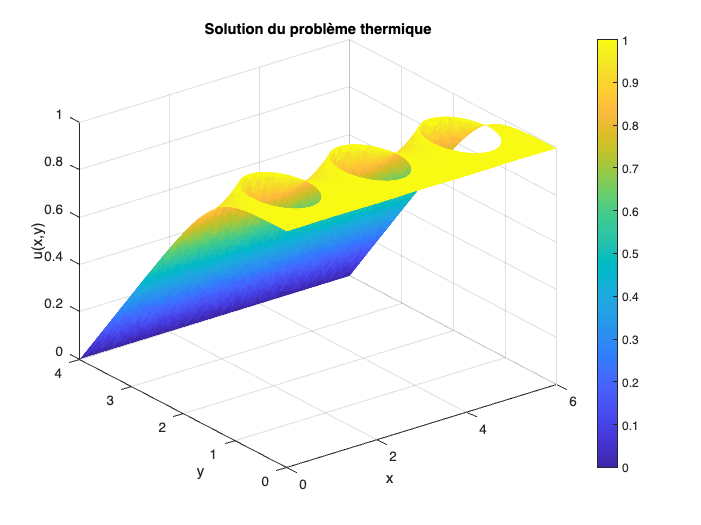



%//// Q19
% Initialisation des données du problème
N = size(P_omega5, 1); % Nombre total de nœuds
M = sparse(N, N);      % Matrice de masse
A = sparse(N, N);      % Matrice de rigidité
b = zeros(N, 1);       % Second membre

% Assemblage des matrices M et A
for k = 1:size(T_omega5, 1)
    nodes = T_omega5(k, :);       % Indices des nœuds du triangle courant
    coords = P_omega5(nodes, :);  % Coordonnées des nœuds du triangle

    % Calcul de l'aire du triangle
    Area = 0.5 * abs(det([1, 1, 1; coords']));

    % Matrice de masse locale
    M_local = (Area / 12) * (ones(3) + eye(3));

    % Matrice de rigidité locale
    [a, b_grad] = base(coords(1, :), coords(2, :), coords(3, :));
    A_local = Area * (a' * a);

    % Assemblage global
    M(nodes, nodes) = M(nodes, nodes) + M_local;
    A(nodes, nodes) = A(nodes, nodes) + A_local;
end

% Conditions initiales
u = zeros(N, 1);  % Température initiale
dt = 0.1;        % Pas de temps
T_max = 1;        % Temps final
N_t = round(T_max / dt);  % Nombre de pas de temps

% Simulation temporelle
figure;
for n = 1:N_t
    % Conditions aux limites
    b(:) = 0;  % Réinitialisation du second membre

    % Imposition des conditions de Dirichlet, nullité au niveau d'un bord
    % extérieur
    for idx = gamma_ext'
        A(idx, :) = 0; A(idx, idx) = 1;
        b(idx) = g_ext(P_omega5(idx, 1), P_omega5(idx, 2));
    end
    % Condition pour les tubes
    for idx = gamma_tube'
        A(idx, :) = 0; A(idx, idx) = 1;
        b(idx) = g_tube(P_omega5(idx, 1), P_omega5(idx, 2));
    end

    % Construction du système linéaire
    lhs = M / dt + A;        % Matrice du système
    rhs = (M / dt) * u + b;  % Second membre

    % Résolution
    u = lhs \ rhs;

    % Visualisation
    trisurf(T_omega5, P_omega5(:, 1), P_omega5(:, 2), u, 'EdgeColor', 'none');
    xlabel('x'); ylabel('y'); zlabel('u(x, y, t)');
    title(['Solution à t = ', num2str(n * dt)]);
    colorbar;
    caxis([0, 1]);  % Échelle de couleur
    pause(0.1);
end

Q22) 

%Lorsque la fréquence de la fonction sinus augmente, c'est comme si on augmentait la densité des ailettes,
% mais leur efficacité individuelle diminue, car la chaleur ne peut pas se répartir uniformément. 
% Ainsi, le flux thermique global diminue malgré une augmentation apparente des points de contact, 
% car ces points deviennent moins efficaces.
% Cette observation souligne une limitation pratique dans la conception des systèmes thermiques : une complexité ou densité excessive (haute fréquence, longue ailette) ne garantit pas une meilleure dissipation thermique globale.